%2025.09.05
%产生密集假目标干扰（延时叠加型）作为分类数据，干噪比30-60dB之间随机；假目标个数3-6个；假目标间延迟时间1-10us；
% close all;clear;clc
j=sqrt(-1);
data_num=2;     %干扰样本数
num_label = 1;  %信号标签
samp_num=8000;  %距离窗点数

fs = 80e6;          % 采样频率 80MHz
ts = 1/fs;          % 采样时间间隔
T = 100e-6;         % 信号时宽 100μs
N = round(T*fs);    % 采样点数
t = (0:N-1)*ts;     % 时间窗口
% t = linspace(0,taup,taup*fs);          %时间序列

%% 1.定义线性调频信号
taup = 10e-6;       % 信号脉宽 10μs
Ntau = round(taup*fs);    % 采样点数
ttau = (-Ntau/2:1:Ntau/2-1)*ts;     % LFM时间窗口
B  = 10e6;          % 信号带宽 10MHz
fc = 40e6           % 中心频率 40MHz

fc = 40000000

left_range = 1691

left_range = 2091

left_range = 2491

left_range = 2891

left_range = 3291

echo_sp =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i 

sp =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


window = 128

left_range = 1677

left_range = 2397

left_range = 3117

left_range = 3837

left_range = 4557

echo_sp =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i 

sp =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


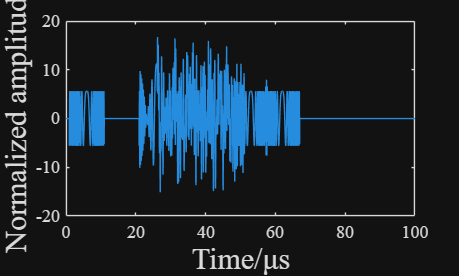

window = 128

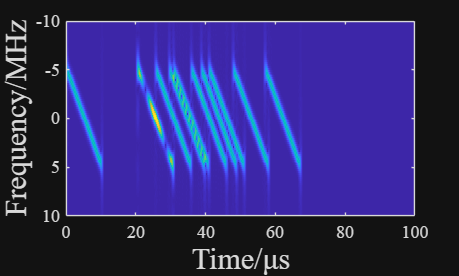

f0 = fc - B/2;      % 起始频率
f1 = fc + B/2;      % 终止频率
% lfm = exp(1j*2*pi*(f0*ttau + (B/(2*taup))*ttau.^2));
lfm = exp(1j*pi*B/taup*ttau.^2);          %LFM信号


SNR=15; %信噪比dB
echo=zeros(data_num,samp_num,3);     %矩阵大小（500,samp_num,2）
echo_stft=zeros(data_num,100,247,3);  %矩阵大小（500,200,1000,2）
noise_echo_DFTJ = zeros(data_num,samp_num) ;
label=zeros(1,data_num)+num_label;
%标签数据,此干扰标签为0
for m=1:data_num
    JNR=15; %30+round(rand(1,1)*30); %干噪比30-60dB
    sp=randn([1,samp_num])+1j*randn([1,samp_num]);%噪声基底
    sp=sp/std(sp);
    white_noise = sp;
    pure_echo = 0*sp;
    noise_echo = 0*sp;

    As=10^(SNR/20);%目标回波幅度
    Aj=10^(JNR/20);%干扰回波幅度
    range_tar=1+round(rand(1,1)*100);
    left_echo = 1+range_tar;
    right_echo = left_echo+length(lfm)-1;
    sp(left_echo:right_echo)=sp(left_echo:right_echo)+As*lfm;  
    
    pure_echo(left_echo:right_echo) = pure_echo(left_echo:right_echo)+As*lfm;
    
    %噪声+目标回波 目标在距离窗内range_tar点处

    k=5;%改为随机产生3-6（个假目标）
    delay_time=(round(rand(1,1)*10))*1e-6;%改为随机延迟1-10us
    delay_num=delay_time*fs;
    
    
    for i=1:k %距离窗内添加多个假目标干扰
        
        % Aj = Aj*(0.5+rand())
        left_range = range_tar+1600+(i-1)*delay_num
        right_range = left_range+length(ttau)-1;
        sp(left_range:right_range)=sp(left_range:right_range)+Aj*lfm;
        noise_echo(left_range:right_range) = noise_echo(left_range:right_range)+Aj*lfm;
    end
    noise_echo_DFTJ(m,1:samp_num) = noise_echo;

    

    sp=sp/max(max(sp));
    sp_abs=abs(sp);
    % 
    echo_sp = [pure_echo;noise_echo_DFTJ]
    sp = sum(echo_sp)
    figure(3)
    plot(linspace(0,100,samp_num),sp);
    set(gca,'FontName','Times New Roman');
    xlabel('Time/μs','FontSize',15);ylabel('Normalized amplitude','FontSize',15)
     
    
    echo(m,1:samp_num,1)=real(sp); 
    echo(m,1:samp_num,2)=imag(sp);
    echo(m,1:samp_num,3)=sp_abs; 
%     echo(m,1:samp_num,4)=angle(sp);%信号实部、虚部分开存入三维张量中
    window = 128    
    [S,F,T] = spectrogram(sp,window,window-8,400,fs,'centered');
    
    S=S/max(max(S));
    S_abs=abs(S);
    figure(4)
    imagesc(linspace(0,100,size(S,1)),linspace(-40,40,size(S,2)),abs(S));
    axis([0 100 -10 10])
    set(gca,'FontName','Times New Roman');
    xlabel('Time/μs','FontSize',15);ylabel('Frequency/MHz','FontSize',15)
    
    echo_stft(m,1:size(S,1),1:size(S,2),1)=real(S);
    echo_stft(m,1:size(S,1),1:size(S,2),2)=imag(S);
    echo_stft(m,1:size(S,1),1:size(S,2),3)=S_abs;
%     echo_stft(m,1:size(S,1),1:size(S,2),4)=angle(S);
    
end

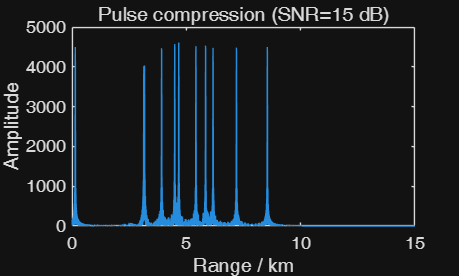

% --- 匹配滤波脉冲压缩 ---
s_ref = lfm;                    % 参考信号 (一定要和生成时一致)
h = conj(flip(s_ref));
y = conv(sp, h);
Np = length(s_ref);
y_aligned = y(Np:end);          % 对齐
env = abs(y_aligned);
env_dB = 10*log10(env.^2 / max(env.^2));


% 距离轴
c = 3e8;
rng_axis = (0:length(env)-1) * c/(2*fs);

% 绘图
figure;
% plot(rng_axis*1e-3, env_dB);
% xlabel('Range / km'); ylabel('Power (dB)');

plot(rng_axis*1e-3, env);
xlabel('Range / km'); ylabel('Amplitude');
title(sprintf('Pulse compression (SNR=%d dB)', SNR));